%parameters needed for stopband butter function
Omega_passband_start = 5*pi/24;
Omega_passband_end = 11*pi/24;
Fs = 1000; % Sampling frequency (not specified in problem)

Fc = 0.0021

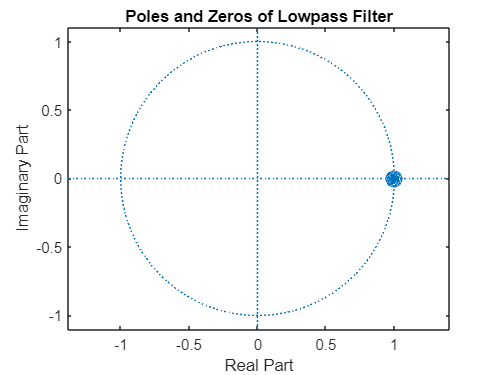

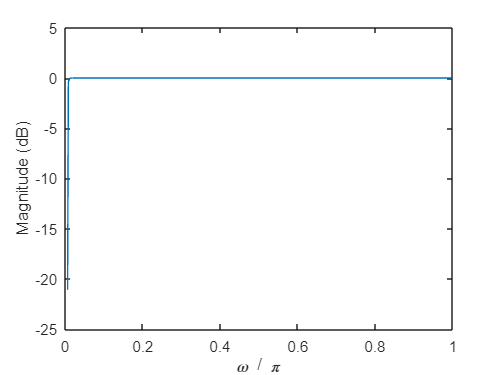

v = [Omega_passband_start/(Fs/2), Omega_passband_end/(Fs/2)];

% Eighth-order digital bandstop filter
[b_bandstop, a_bandstop] = butter(8, v, 'stop');
figure;
zplane(b_bandstop, a_bandstop);
title('Poles and Zeros of Bandstop Filter');
figure;
freqz(b_bandstop, a_bandstop);
title('Magnitude Response of Bandstop Filter');